# Part 2: Separation vs. Isolation

Analyses for Experiment 2

## A Indices for Sep-Iso comparisons

xticklabels = {'ISO' 'SEP' 'CTL'};
exp_ind = find(strcmp(rdb.experiment, 'cof'));
 
 cof_iso_ind = intersect(exp_ind, find(rdb.condition(:,4) == 0 & rdb.condition(:,2) == 24));
 cof_sep_ind = intersect(exp_ind, find(rdb.condition(:,4) == 1));
 cof_min_ind = intersect(exp_ind, find(rdb.condition(:,2) == 1/60));
 
 cofind = cell(3,1);
 [~, sortind] = sort(rdb.degunumbers(cof_iso_ind,1));
 cofind{1} = cof_iso_ind(sortind);
 [~, sortind] = sort(rdb.degunumbers(cof_sep_ind,1));
 cofind{2} = cof_sep_ind(sortind);
 [~, sortind] = sort(rdb.degunumbers(cof_min_ind,1));
 cofind{3} = cof_min_ind(sortind);
 
 condvec = [1:3];
 
 
[u_pairs, ia_pairs, ic_pairs] = unique(rdb.degunumbers(exp_ind,:), 'rows');
 
 betypes = [-1 1 2 3];
  behaviortypes = {'Agonistic' 'Grooming' 'Rear-sniffing' 'Face-to-face'};
 phystypes = betypes; %might have used wrong variable name so this is just a catch 
 

## B Physical interactions

### B.2 Physical interactions, combined

 septime_mat = nan(length(u_pairs),length(cofind),length(phystypes));
 for i = 1:size(u_pairs,1)
    for j = 1:length(cofind)
         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:, 2) == u_pairs(i,2)), cofind{j});
         septime_mat(i,j,1:length(betypes)) = sum(rdb.sumbehav(curind,:),1);
    end
 end


Figure of total physical interaction data

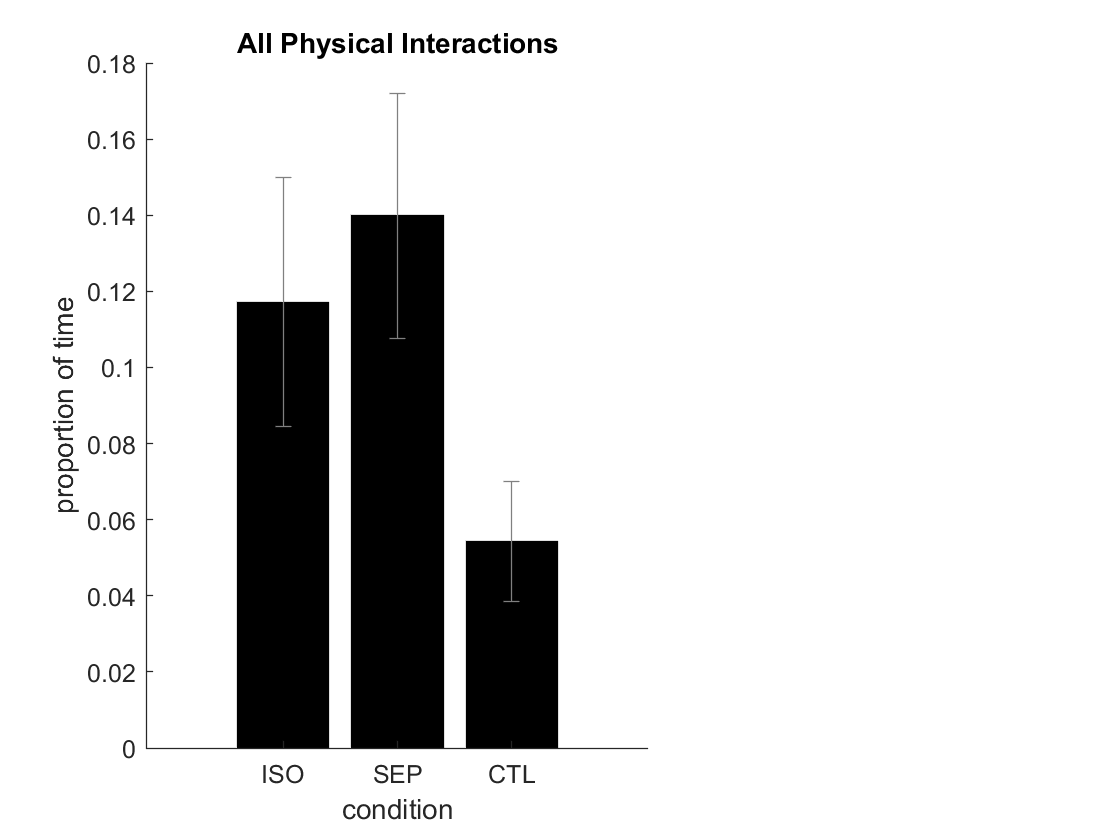

 stm_all = nansum(septime_mat,3);
% not normalized:
 figure
 f2A = subplot(1,5,1:3);
 bar(1:3, nanmean(stm_all), 'FaceColor', 'k');
 hold on;
 eb = errorbar(1:3, nanmean(stm_all), nanstd(stm_all)/sqrt(size(septime_mat,1)-1), 'LineStyle', 'none', 'Color', [.5 .5 .5]);
 set(f2A, 'XTickLabel', xticklabels);
 set(get(f2A, 'XLabel'), 'String', 'condition');
 set(get(f2A, 'YLabel'), 'String', 'proportion of time');
 set(get(f2A, 'Title'), 'String', 'All Physical Interactions');
 box off

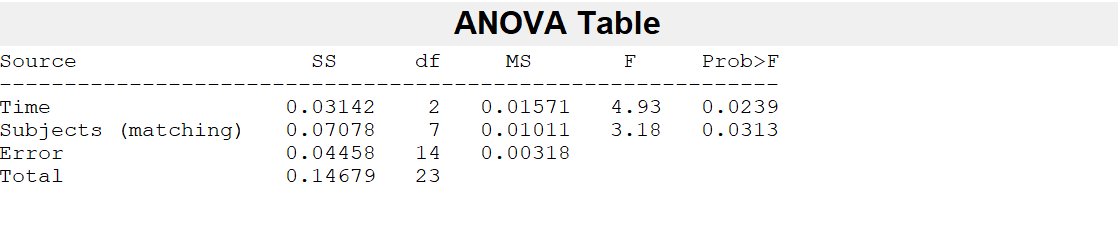

 [p, table] = anova_rm(stm_all);

 
 [a, b, ~, ss] = ttest(stm_all(:,2)-stm_all(:,3))

a = 1

b = 0.0056

ss = struct with fields:
    tstat: 3.9402
       df: 7
       sd: 0.0614


cd = mean(stm_all(:,2)-stm_all(:,3))/std(stm_all(:,2)-stm_all(:,3))

cd = 1.3931

 
[a, b, ~, ss] = ttest(stm_all(:,1)-stm_all(:,3))

a = 0

b = 0.0999

ss = struct with fields:
    tstat: 1.8953
       df: 7
       sd: 0.0938


cd = mean(stm_all(:,1)-stm_all(:,3))/std(stm_all(:,1)-stm_all(:,3))

cd = 0.6701



 [a, b, ~, ss] = ttest(stm_all(:,1)-stm_all(:,2))

a = 0

b = 0.4538

ss = struct with fields:
    tstat: -0.7930
       df: 7
       sd: 0.0808


 
 [a, b, ~, ss] = ttest2(stm_all_iso(2:end,1), stm_all(:,1))

a = 1

b = 0.0337

ss = struct with fields:
    tstat: -2.3545
       df: 14
       sd: 0.0652


 [a, b, ~, ss] = ttest2(stm_all_iso(2:end,3), stm_all(:,3))

a = 1

b = 0.0385

ss = struct with fields:
    tstat: 2.2838
       df: 14
       sd: 0.0607


  [a, b, ~, ss] = ttest2(stm_all_iso(:,1), stm_all(:,2))

a = 1

b = 0.0100

ss = struct with fields:
    tstat: -2.9464
       df: 15
       sd: 0.0643


    [a, b, ~, ss] = ttest2(stm_all_iso(:,3), stm_all(:,2))

a = 0

b = 0.6335

ss = struct with fields:
    tstat: -0.4867
       df: 15
       sd: 0.0777


### B.2 Physical interaction types

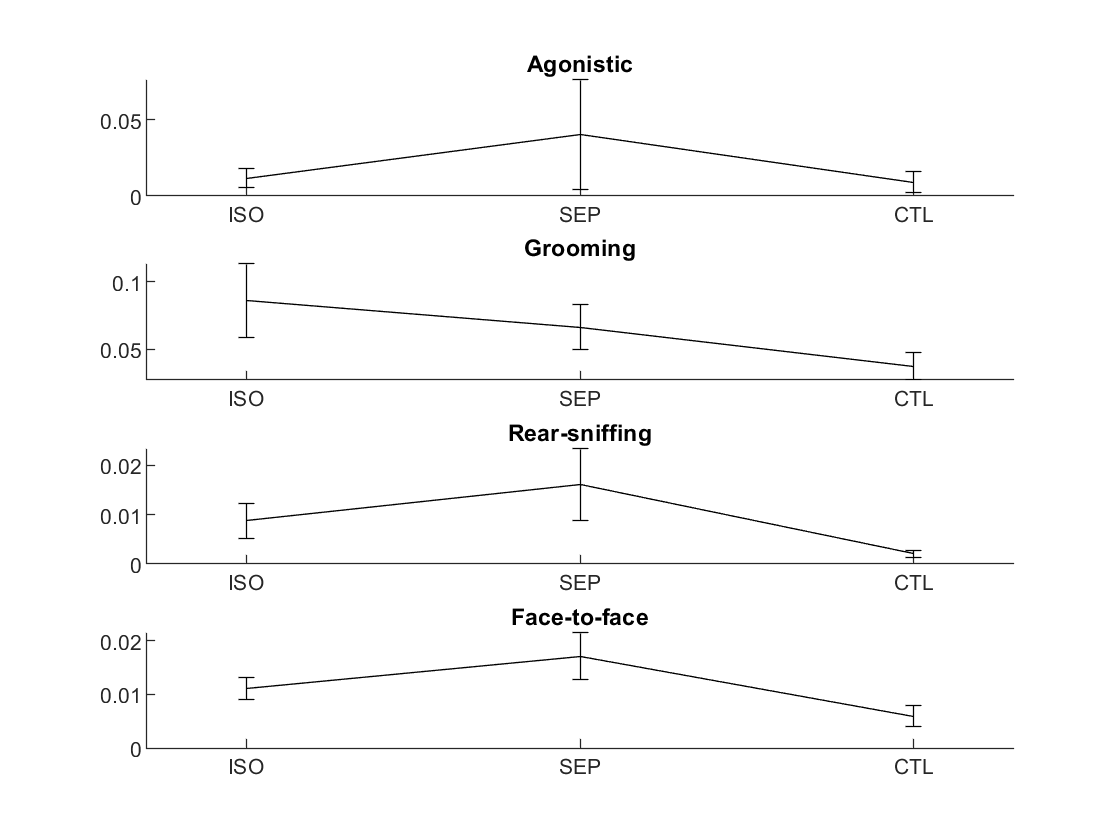



figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septime_mat(:,:,i)), nanstd(septime_mat(:,:,i))/sqrt(size(septime_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end

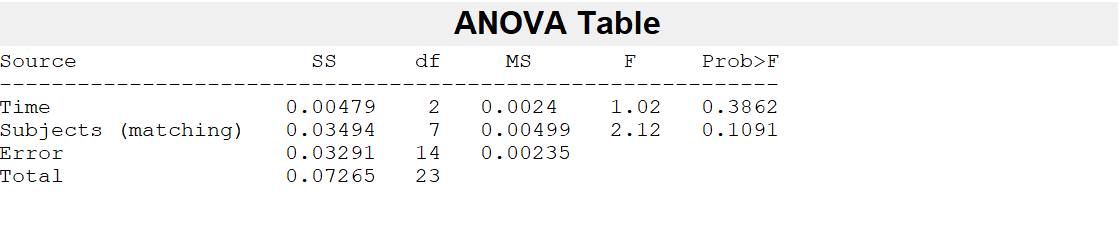

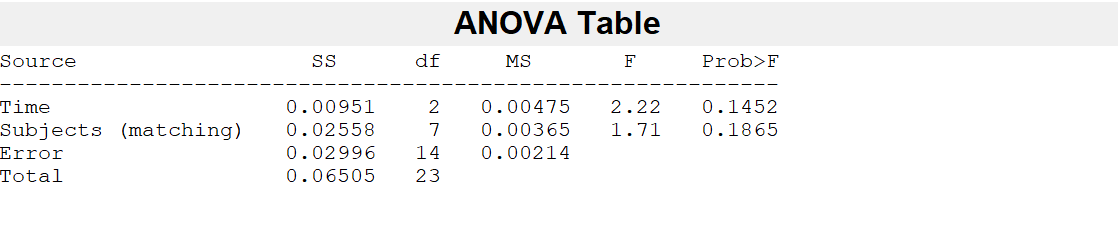

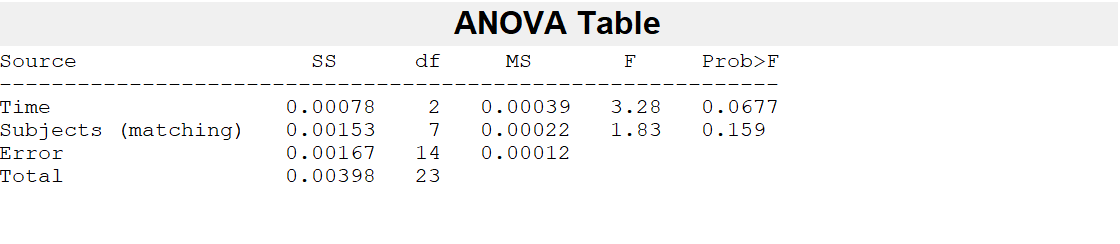

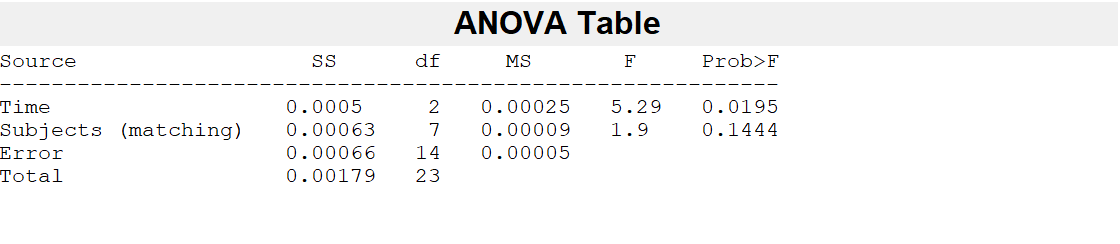

 clear aa2 bb2
 for i = 1:4
     [a(i) b(i)] = ttest(septime_mat(:,1,i)-septime_mat(:,2,i));
     [aa2(i) bb2(i)] = ttest(septime_mat(:,2,i)-septime_mat(:,3,i));
     [psub(i,:) j] = anova_rm(septime_mat(:,:,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end

 
 b

b =     0.3933    0.3597    0.2626    0.1086


 bb2

bb2 =     0.2886    0.2098    0.0737    0.0273


 
 s = septime_mat(:,1:2,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');


2-way repeated measures ANOVA in R

 Create_2way_R_table(septime_mat(:,1:2,:));
 
 % Have to use R script for stats (e.g., repeatedmeasures_NIscript.R)
 
 

Quick check to see if the allogrooming vs. rear-sniffing ratio is different between ISO and SEP

 
 f = figure

rBR = septime_mat(:,:,2)./septime_mat(:,:,3);
rBR(isinf(rBR)) = nan;
zrBR = zscore(rBR(:,1:2)')';

f2B2 = errorbar(1:2, nanmean(zrBR), nanstd(zrBR), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
   % set(f2B2, 'XTick', [1:3]);
   %  set(f2B2, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
%    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(f, 'Children'), 'XLim', [.7 3.3]);
     box off
[a b] = ttest(rBR(:,1)-rBR(:,2))

Running type analysis again on the half-session time


sumbehav_half =  reun_mksumbehav(rdb, betypes, 1, 600);

 septimeH_mat = nan(length(u_pairs),length(condvec),length(phystypes));
 for i = 1:size(u_pairs,1)
    for j = 1:length(cofind)
         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:, 2) == u_pairs(i,2)), cofind{j});
         septimeH_mat(i,j,1:length(phystypes)) = sum(sumbehav_half(curind,:),1);
    end
 end

figure
 for i = 1:4
%     f2B = subplot(4,3,i*3);
    f2B = subplot(4,1,i);
     %bar(1:3, nanmean(septime_mat(:,:,i)));
     hold on
     e_sub = errorbar(1:3, nanmean(septimeH_mat(:,:,i)), nanstd(septimeH_mat(:,:,i))/sqrt(size(septimeH_mat,1)-1), 'k'); %'LineStyle', 'none');
%    ax = gca;
%    ax.Clipping = 'off';
    set(f2B, 'XTick', [1:3]);
     set(f2B, 'XTickLabel', xticklabels);
  %  set(get(f1B, 'XLabel'), 'String', 'condition');
 %   set(get(f1B, 'YLabel'), 'String', 'proportion of time');
    set(get(f2B, 'Title'), 'String', behaviortypes{i});
    set(get(e_sub, 'Parent'), 'XLim', [.7 3.3]);
     box off
 end
 clear a b
 for i = 1:4
     [a(i) b(i)] = ttest(septimeH_mat(:,1,i)-septimeH_mat(:,2,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
 end
 
 b
  for i = 1:4
     [a(i) b(i)] = ttest(septimeH_mat(:,1,i)-septimeH_mat(:,3,i));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
  end
  b
 
 s = septimeH_mat(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

### B.3 Distribution over time

% A.Cumulative activity over time

 cumsum_f_a_d1 = nan(length(u_pairs), 601, length(cofind));
h_cs_f_a = nan(length(u_pairs), length(cofind));
 
 for k = 1:length(cofind)
    for i = 1:size(u_pairs,1)
        
        curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
  
        cumsum_f_a_d1(i,:,k) = cumsumbehav(curind,:);
        h_cs_f_a(i,k) = cumsumbehav_ht(curind);
        
        
    end
 end

Display cumsums

 figure
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_paircodes)-1), 'k:');
% hold on
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_paircodes)-1), 'k--');
% errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_paircodes)-1), 'k-');
% 

errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 1)), nanstd(cumsum_f_a_d1(:, :, 1))/sqrt(length(u_pairs)-1), 'Color', [.85 0 0]);
hold on
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 2)), nanstd(cumsum_f_a_d1(:, :, 2))/sqrt(length(u_pairs)-1), 'Color', [0 .55 .65]);
errorbar_alt(0:2:1200, nanmean(cumsum_f_a_d1(:, :, 3)), nanstd(cumsum_f_a_d1(:, :, 3))/sqrt(length(u_pairs)-1), 'Color', [0 0 0]);

box off

clear a b 
for i = 1:600
     [a(i) b(i)] = ttest(cumsum_f_a_d1(:,i,1)-cumsum_f_a_d1(:,i,2));
 end
 [min_sepiso locmin_sepiso] = min(b)
 
 [h, p, ci, stats] = ttest(cumsum_f_a_d1(:,30, 1) - cumsum_f_a_d1(:,30,2));
 stats
 p
 


Compare latency to half-amplitude

[a, b, ~, dsd] = ttest(h_cs_f_a(:,1)-h_cs_f_a(:,2))

Latency data: Compute the matrix for this experiment

latmat_f = nan(length(u_pairs), length(phystypes), length(cofind));
latmat5_f = nan(length(u_pairs), length(phystypes), length(cofind));
 for i = 1:length(u_pairs)
     for k = 1:length(cofind)
         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
         latmat_f(i,:, k) = be_lat(curind,:);    
         latmat5_f(i,:,k) = be_lat5(curind,:);
     end
 end

Display latencies, collective

 f = figure
lm = min(latmat_f, [], 2);
bar(nanmean(squeeze(lm)), 'k')
hold on
errorbar(1:3, nanmean(squeeze(lm)), nanstd(squeeze(lm))/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', xticklabels);

slm = squeeze(lm);
p = anova_rm(squeeze(slm));

Display the latencies across types

titlecell = {'agonistic', 'body sniffing', 'rear sniffing', 'face-to-face'};

 figure
 
 for i = 1:length(betypes)
    d = subplot(length(betypes),1,i);
    
    errorbar(1:length(condvec), nanmean(squeeze(latmat5_f(:, i,:))), nanstd(squeeze(latmat5_f(:,i,:)))/sqrt(8), 'k');
%    hold  on
   set(d, 'XLim', [.75 3.25]);
   set(d, 'XTick', [1:3])
   if i < 4
       set(d, 'XTickLabel', {'' '' '' });
   else
       set(d, 'XTickLabel', xticklabels);
   end
   title(titlecell{i});
    box off
 end

Stats on latencies

for i = 1:4
    [a(i) b(i)] = ttest(squeeze(latmat5_f(:,i,1)- latmat5_f(:,i,2)));
  %   [psub(i,:) j] = anova_rm(squeeze(latmat5_f(:,i,1:2)));
%     sheetnum = ['Sheet' num2str(i)];
%     xlswrite('SeparationEffectOnPhysical_Sheets_1Agonistic_2groom_3rearsniff_4faceface.xls', septime_mat(:,:,i), sheetnum);       
end
b

### B.4 Temporal relationships between interactions


%  exp_ind = find(strcmp(rdb.experiment, 'cof'));
%  
%  cof_iso_ind = intersect(exp_ind, find(rdb.condition(:,4) == 0));
%  cof_sep_ind = intersect(exp_ind, find(rdb.condition(:,4) == 1));
%  cof_min_ind = intersect(exp_ind, find(rdb.condition(:,2) == 1/60));
%  
%  cofind = cell(3,1);
%  cofind{1} = cof_iso_ind;
%  cofind{2} = cof_sep_ind;
%  cofind{3} = cof_min_ind;


colorcodes = [.85 0 0; 0 .55 .65];

figure
%i = 1;
for i = 1:2
    for j = 1:16
        subplot(4,4,j);
        hold on
        curind = cofind{i};

        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,curind))'), nanstd(squeeze(be_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(i,:))  ;  
%        hold on
%        errorbar_alt(xaxis, nanmean(squeeze(SH_xcorr(j,:,curind))'), nanstd(squeeze(SH_xcorr(j,:,curind))')/sqrt(length(curind)-1), 'Color', colorcodes(2,:))  ; 
        box off
    end    
    
end


% stats 
mxc = nan(size(be_xcorr,1), 2, size(be_xcorr,3));

mxc(:,1,:) = nanmean(be_xcorr(:,1:19,:),2);
mxc(:,2,:) = nanmean(be_xcorr(:,23:42,:),2);

sxc(:,1,:) = nanmean(SH_xcorr(:,1:19,:),2);
sxc(:,2,:) = nanmean(SH_xcorr(:,23:42,:),2);

cofind;

for i = 1:16
    [asi1(i), bsi1(i), ~, dsi1(i)] = ttest(mxc(i,1,cofind{1}) - mxc(i,1,cofind{2}));
end

for i = 1:16
    [asi2(i), bsi2(i), ~, dsi2(i)] = ttest(mxc(i,2,cofind{1}) - mxc(i,2,cofind{2}));
end

[codes(:,1:2,1) bsi1' bsi2' [dsi1(:).tstat]' [dsi2(:).tstat]']



Temporal relationship figure for paper

figure
subplot(1,2,1)
hold on
curind = find(ismember(rdb.condition(:,1), 3));
%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [.7 .7 .7]);

plot(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'),  'Color', [.85 0 0], 'LineWidth', 2, 'LineStyle', ':');

%curind = cofind{3};
%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [0 0 0]);

curind = cofind{1};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [.85 0 0]);
curind = cofind{2};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [0 .55 .65]);
box off

subplot(1,2,2)
hold on
curind = find(ismember(rdb.condition(:,1), 3));
plot(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'),  'Color', [.85 0 0], 'LineWidth', 2, 'LineStyle', ':');

%curind = cofind{3};
%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(10,:,curind))'), nanstd(squeeze(be_xcorr(10,:,curind))')/sqrt(length(curind)-1), 'Color', [0 0 0]);


%errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'), nanstd(squeeze(be_xcorr(8,:,curind))')/sqrt(length(curind)-1), 'Color', [.7 .7 .7]);
curind = cofind{1};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'), nanstd(squeeze(be_xcorr(8,:,curind))')/sqrt(length(curind)-1), 'Color', [.85 0 0]);
curind = cofind{2};
errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(8,:,curind))'), nanstd(squeeze(be_xcorr(8,:,curind))')/sqrt(length(curind)-1), 'Color', [0 .55 .65]);
box off

Let's look at distribution of interaction time

(This analysis turned out to be totally boring)

% %inthist was created in Part 0
% 
% inthist_isosep = nan(length(u_pairs), size(inthist,2), length(cofind));
% mhist_isosep = nan(length(u_pairs), length(cofind), length(betypes));
% 
%  for i = 1:length(u_pairs)
%      for k = 1:length(cofind)
%          curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
%          inthist_isosep(i,:,k) = inthist(curind,:,2);  %focusing in on the body sniffing....            
%          mhist_isosep(i,k,:) = meanint(curind,:);
%      end    
%  end

 

%  for i = 1:4
%      subplot(4,1,i)
%      errorbar(1:3, nanmean(mhist_isosep(:,:,i)), nanstd(mhist_isosep(:,:,i))/sqrt(7))
%      box off
%  end
 
 


%  figure
% colorcodes = [0 0 1 ; 1 0 0];
%  for i = 1:8
%      for j = 1:2         
%          subplot(8,1, i);
%          hold on;
%          plot(inthist_isosep(i,:,j), 'Color', colorcodes(j,:));
%          plot(inthist_isosep(i,:,j), 'Color', colorcodes(j,:));
%          box off
%      end
%  end
 

2-way repeated measures ANOVA in R

% for i = 1:size(latmat_f)
%     nlatmat_f(i,:,:) = squeeze(latmat5_f(i,:,:))';    
% end
% Create_2way_R_table(nlatmat_f(:,1:2,:));
 
 % Have to use R script for stats (e.g., repeatedmeasures_NIscript.R)
 
 

## C: Separation vs. Isolation, VOCALIZATIONS

Rather than re-doing this several times, let's make the sepvoctime_mat

out of whichever variable we are most interested at the moment

options are:

sumvoc -- all syllables

nsumvoc -- all syllables, exclusing nans

csumvoc -- syllables combined into "calls"

rsumvoc -- the rate of syllables, rather than the proportion of time (number instead of time) 

%

### C.1 summed vocalizations

%A lot of this code comes directly from reunionOTRA2.mlx

sv = rsumvoc; %plug in another option, depending on interest

 sepvoctime_mat = nan(length(u_pairs),length(cofind));
 vocnum_mat = sepvoctime_mat;
% svt_4 = nan(length(u_paircodes),3,2);
% side_svt = svt_4;

 for i = 1:length(u_pairs)
     for k = 1:length(cofind)
         curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});
         sepvoctime_mat(i, k) = sv(curind,:);    
         vocnum_mat(i, k) = nsumvoc(curind,:); %this is a weird way to jump back to the voc nums, but moving on 
     end
 end

f = figure
 curmat = sepvoctime_mat;
%curmat = vocnum_mat;

 bar(nanmean(curmat), 'k')
hold on
errorbar(1:3, nanmean(curmat), nanstd(curmat)/sqrt(8), 'Color', [.5 .5 .5], 'LineStyle', 'none')
box off
set(get(f, 'Children'), 'XTick', [1:3])
set(get(f, 'Children'), 'XTickLabel', xticklabels);

p = anova_rm(sepvoctime_mat)
p = anova_rm(vocnum_mat);
[a, b, ~, d] = ttest(sepvoctime_mat(:,1)-sepvoctime_mat(:,3))


### C.2 Vocalizations by type

sv = rvoc;

sepvoctime_mat_full = nan(length(u_pairs), length(cofind), length(indvocsgood));

 for i = 1:length(u_pairs)
     for k = 1:length(cofind)
        curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{k});

         sepvoctime_mat_full(i, k, :) = sv(curind,:);    
     end
 end

Figures

 f4 = figure;


 hold on
b1 = bar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', 'BarWidth', .15, 'FaceColor', [.85 0 0 ]);
b2 = bar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', 'BarWidth', .15, 'FaceColor', [0 .55 .65]);
b3 = bar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:)))', 'BarWidth', .15, 'FaceColor', [0 0 0]);
e1 = errorbar((1:15)-.2, squeeze(nanmean(sepvoctime_mat_full(:,1,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e2 = errorbar((1:15), squeeze(nanmean(sepvoctime_mat_full(:,2,:)))', squeeze(nanstd(sepvoctime_mat_full(:,1,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
e3 = errorbar((1:15)+.2, squeeze(nanmean(sepvoctime_mat_full(:,3,:) )), squeeze(nanstd(sepvoctime_mat_full(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none', 'CapSize', .1);
%bar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), 'BarWidth', .35);
%errorbar([2 4.5 7 9.5], squeeze(nanmean(voctime_mat(:,2,:) )), squeeze(nanstd(voctime_mat(:,2,:) )/sqrt(6)), 'k', 'LineStyle', 'none');
set(get(f4, 'Children'), 'XTickMode', 'manual')
set(get(f4, 'Children'), 'XTick', 1:15)
ivg = indvocsgood; %([1:6 8:end]);
set(get(f4, 'Children'), 'XTickLabel', rdb.voctypes(ivg))
set(get(f4, 'Children'), 'XTickLabelRotation', 60)

 sVM_chit = sepvoctime_mat_full(:,:,5)
sVM_nc = nansum(sepvoctime_mat_full(:,:,[1:4 6:end]), 3)
 nc2c = sVM_nc./(sVM_chit+sVM_nc)
 [a b] = ttest(nc2c(:,2) - nc2c(:,1))
 


curmat = sepvoctime_mat_full;

s = size(curmat);

toprowDM = cell(1,s(2)*s(3));
idatamat = cell(s(2)*s(3),2);
for i = 1:s(2)
    for j = 1:s(3)
        toprowDM{i+(j-1)*s(2)} = ['B' num2str(i) 'C' num2str(j)]; 
        idatamat{i+(j-1)*s(2),1} = ['B' num2str(i)];
        idatamat{i+(j-1)*s(2),2} = ['C' num2str(j)];
    end
end

datamat = num2cell(reshape(curmat, s(1), s(2)*s(3),1));
full_dm = [[{'subject'} toprowDM] ; [num2cell([1:size(datamat,1)]') datamat]];
T = cell2table(full_dm(2:end,:), 'VariableNames', full_dm(1,:));
writetable(T,'datamat.csv');

To do the stats, need to be running R

%!C:\Program Files\R\R-3.6.1\bin\x64\Rscript

full_idm = [{'B' 'C'} ; idatamat];
iT = cell2table(full_idm(2:end,:), 'VariableNames', full_idm(1,:));
writetable(iT,'idatamat.csv');

 s = sepvoctime_mat_full(:,1:3,:);
 be = ones(size(s));
 for i = 1:size(s,3)
     be(:,:,i) = i;
 end
 cn = repmat(1:size(s,2), size(s,1), 1, size(s, 3));
 
 sr = reshape(s, size(s,1)*size(s,2)*size(s,3), 1);
 br = reshape(be, size(s,1)*size(s,2)*size(s,3), 1);
 cr = reshape(cn, size(s,1)*size(s,2)*size(s,3), 1);
 
 
 [p t s] = anovan(sr, [br cr], 'model', 'interaction');

### C.3 Automated clustering

#### C.3.a SEP vs. ISO

inds = cell(9,2);
conds = [1 2 3];

for i = 1:length(u_pairs)
    for j = 1:3
        curind = intersect(find(rdb.degunumbers(:,1) == u_pairs(i,1) & rdb.degunumbers(:,2) == u_pairs(i,2)), cofind{conds(j)});
        inds{i,j} = find(indfeat_nn(:,1) == curind); 
%        vip_inds{i,j} = intersect(inds{i,j}, vocind_best);
    end
end

Assess significance of the clusters

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 2]), 0, [], 9);
%save isosep_sigclusts pvals_c ef_c val_c
load isosep_sigclusts

[isosep_prevocbest, isosep_vocindbest, isosep_irc, isosep_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);
isosep_nm

What are the features and manual classifications associated with the most differentially expressed vocalization?

[h1, h2, h3, h4] = sigclust_Figures(isosep_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

% 
%  [maxef, ind_bestclustnum] = max(efmat(1,:));
% spv = squeeze(pvals(:,ind_bestclustnum,:));
% sev = squeeze(ef(:,ind_bestclustnum,:));
% 
% for i = 1:size(spv,2)
%     rowmin2(i) = find(spv(:,i) == min(spv(:,i)));
%     pvb2{i} = idx{ind_bestclustnum, i} == rowmin2(i);
% end
% 
% curisig = nan(length(pvb2));
% for i = 1:length(pvb2)
%     for j = 1:length(pvb2)
%         if i ~= j
%             curisig(i,j) = rand_index(pvb2{i}, pvb2{j});
%         end
%         
%     end
% end
% 
% arisig = nanmean(nanmean(curisig));
% % hold
% % box off
% % plot(20, arisig, 'r*')



#### C.3.b  ISO vs. CTL

%[pvals_c, ef_c, val_c, irc_m] = sigclust_recursive(idx, inds(:,[1 3]), 0, [], 9);
%save iso2_sigclusts pvals_c ef_c val_c
load iso2_sigclusts

[iso2_prevocbest, iso2_vocindbest, iso2_irc, iso2_nm] = process_sigclusts(pvals_c, ef_c, val_c,  idx, indfeat_nn);
iso2_nm

What are the features and manual classifications associated with the most differentially expressed vocalization?

[h1, h2, h3, h4] = sigclust_Figures(iso2_prevocbest, goodc, featset_nn, identcodes_nn, indvocsgood, rdb.voctypes(ivg), y);

% 
%  [maxef, ind_bestclustnum] = max(efmat(1,:));
% spv = squeeze(pvals(:,ind_bestclustnum,:));
% sev = squeeze(ef(:,ind_bestclustnum,:));
% 
% for i = 1:size(spv,2)
%     rowmin2(i) = find(spv(:,i) == min(spv(:,i)));
%     pvb2{i} = idx{ind_bestclustnum, i} == rowmin2(i);
% end
% 
% curisig = nan(length(pvb2));
% for i = 1:length(pvb2)
%     for j = 1:length(pvb2)
%         if i ~= j
%             curisig(i,j) = rand_index(pvb2{i}, pvb2{j});
%         end
%         
%     end
% end
% 
% arisig = nanmean(nanmean(curisig));
% % hold
% % box off
% % plot(20, arisig, 'r*')

### C.4 Cross-examine clusters across 3 comparisons

% isosep_prevocbest;
% isosep_vocindbest;
% iso_prevocind;
% iso_vocind;
% iso2_prevocind;
% iso2_vocind;

%

length(intersect(isosep_prevocbest{1}, iso_prevocbest{1}))/length(union(isosep_prevocbest{1}, iso_prevocbest{1}))
%chance overlap
% Actually: this is difficult to estimate since we have to look only at
% those syllables expressed in the sessions of interest
(length(isosep_prevocbest{1})/length(y) * length(iso_prevocbest{1})/length(y))  /  (length(union(isosep_prevocbest{1}, iso_prevocbest{1})))
rand_isosep = randperm(length(y), length(isosep_prevocbest{1}));
rand_iso = randperm(length(y), length(iso_prevocbest{1}));

length(intersect(rand_isosep, rand_iso))/length(union(rand_isosep, rand_iso))

for i = 1:3
    length(intersect(iso2_prevocbest{i}, iso_prevocbest{1}))/length(union(iso2_prevocbest{i}, iso_prevocbest{1}))
end

sanity check on each:

% requires that you have the sigclusts variable in your current working
% directory!

load iso_sigclusts
iso_pvals = pvals_c;
iso_ef = ef_c;
iso_vals = val_c;

load isosep_sigclusts
isosep_pvals = pvals_c;
isosep_ef = ef_c;
isosep_vals = val_c;

load iso2_sigclusts
iso2_pvals = pvals_c;
iso2_ef = ef_c;
iso2_vals = val_c;


[iso_pvals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
    iso_vals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]

[isosep_pvals{1}(isosep_irc(1,2), isosep_irc(1,1), isosep_irc(1,3))...
    isosep_vals{1}(isosep_irc(1,2), isosep_irc(1,1), isosep_irc(1,3))]
for i = 1:3 % I intentionally left pvals and vals index at "1" to look at original classifications, not syllable-removed classes
[iso2_pvals{1}(iso2_irc(i,2), iso2_irc(i,1), iso2_irc(i,3))...
    iso2_vals{1}(iso2_irc(i,2), iso2_irc(i,1), iso2_irc(i,3))]
end

Now how are they expressed in other cases?

Iso on isosep

[isosep_pvals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
    isosep_vals{1}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]

Iso on iso2

for i = 1:3
[iso2_pvals{i}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))...
    iso2_vals{i}(iso_ircm(1,2), iso_ircm(1,1), iso_ircm(1,3))]
end

how did the original cluster do on the current iso vs. 1 min?



pvals(iso_bestvoc_bcn_row_col(2), iso_bestvoc_bcn_row_col(1), iso_bestvoc_bcn_row_col(3))
vals(iso_bestvoc_bcn_row_col(2), iso_bestvoc_bcn_row_col(1), iso_bestvoc_bcn_row_col(3))
pvals(isosep_bestvoc_bcn_row_col(2), isosep_bestvoc_bcn_row_col(1), isosep_bestvoc_bcn_row_col(3))
vals(isosep_bestvoc_bcn_row_col(2), isosep_bestvoc_bcn_row_col(1), isosep_bestvoc_bcn_row_col(3))